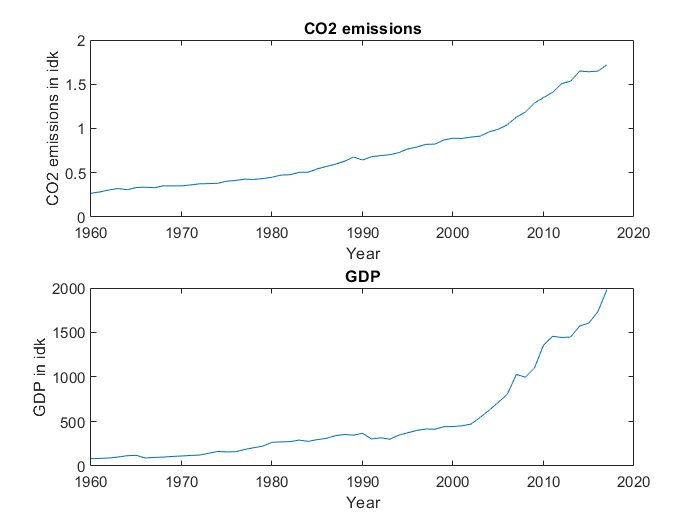

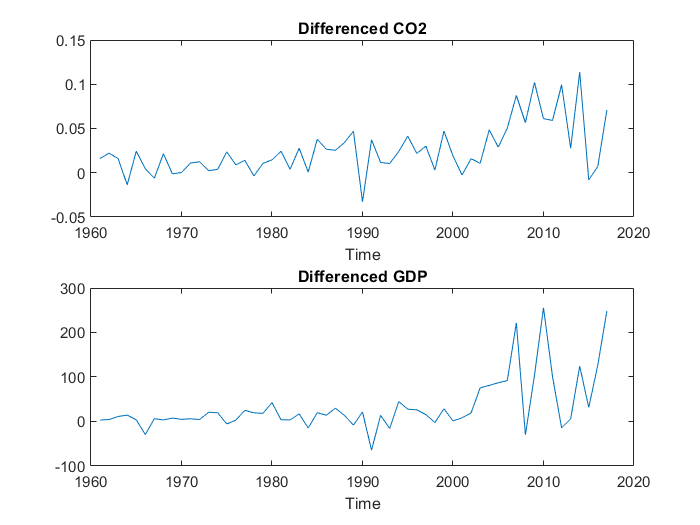

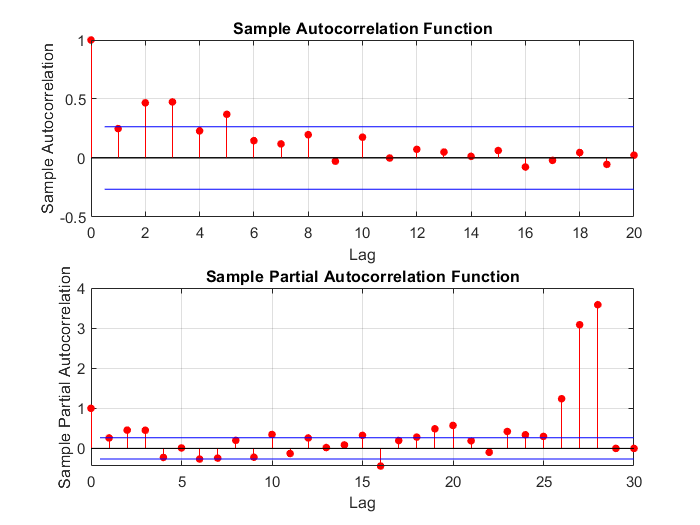

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0012076      0.0018292       0.66015         0.50915
    AR{1}          0.98093       0.062976        15.576       1.057e-54
    MA{1}         -0.83351        0.13358       -6.2396      4.3879e-10
    Variance    0.00059875      8.779e-05        6.8202      9.0912e-12



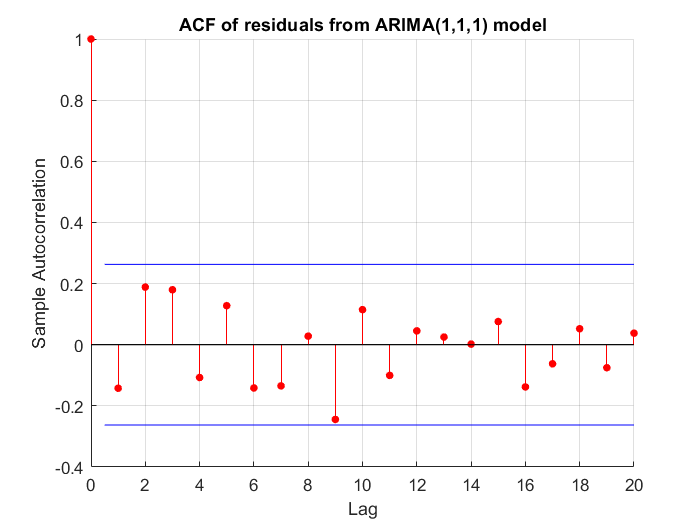

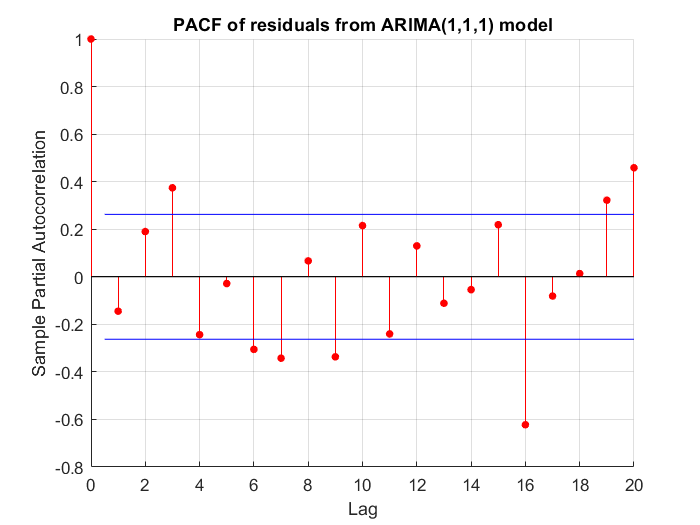

Whiteness Test for Residuals results


   0

    0.5008



 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0              0           NaN             NaN
    AR{1}          0.53268        0.12221        4.3586      1.3091e-05
    AR{2}          0.43326        0.10482        4.1335      3.5726e-05
    MA{1}         -0.50009        0.13742        -3.639      0.00027368
    Variance    0.00056552     9.1572e-05        6.1757      6.5852e-10



Whiteness Test for Residuals results


   0

    0.6497



 
   ARIMA(2,1,1) Model (Gaussian Distribution)
 
    Effective Sample Size: 58
    Number of Estimated Parameters: 4
    LogLikelihood: 134.556
    AIC: -261.112
    BIC: -252.871
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0              0           NaN             NaN
    AR{1}          0.53268        0.12221        4.3586      1.3091e-05
    AR{2}          0.43326        0.10482        4.1335      3.5726e-05
    MA{1}         -0.50009        0.13742        -3.639      0.00027368
    Variance    0.00056552     9.1572e-05        6.1757      6.5852e-10

 
 


clear; close all;

## Open data

path = "./Data/india_data.xlsx";
% opts = detectImportOptions(path);
T = readtable(path,"ReadRowNames",true);
data = table2array(T)';
% Finding the first NAN value and taking data upto the instance before it
cut_off = length(data(:,1));
for i = 1:length(data(:,1))
    if (sum(isnan(data(i,:))))
        cut_off = i-1;
        break;
    end
end
time = data(1:cut_off,1);
Data = data(1:cut_off,2:end);

## Visualisation

n = length(time);
m = length(Data(1,:));
subplot(2,1,1);
plot(time,Data(:,1));
title('CO2 emissions'); 
ylabel('CO2 emissions in idk'); xlabel('Year');
subplot(2,1,2);
plot(time,Data(:,2));
title('GDP'); 
ylabel('GDP in idk'); xlabel('Year');

From the plot we see non-stationarity of trend type (not random walk) as would be expected.

## Test for integrating effects

results = zeros(m,2);
for i = 1:m
    [results(i,1), results(i,2)] = adftest((Data(:,i)));
end
% Unit root test not rejected for both GDP and CO2 => has integrating
% effects
CO2 = (Data(:,1));
diff_CO2 = diff(CO2);
[hCO2,pCO2] = adftest(diff_CO2);
diff_GDP = diff(Data(:,2));
[hGDP,pGDP] = adftest(diff_GDP);
figure;
subplot(211);plot(time(2:end),diff_CO2);title("Differenced CO2");xlabel("Time");
subplot(212);plot(time(2:end),diff_GDP);title("Differenced GDP");xlabel("Time");

Null hypothesis rejected, the differenced series does not have any integrating effects! This implies the order of integration in the data is 1.

## ARIMA model for CO2

figure;
subplot(211); autocorr(diff_CO2);
subplot(212); parcorr(diff_CO2,"NumLags",30);

% try arima(5,1,3)
vk = CO2;
model1 = arima(1,1,1); 
model1_est = estimate(model1,vk);

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0012076      0.0018292       0.66015         0.50915
    AR{1}          0.98093       0.062976        15.576       1.057e-54
    MA{1}         -0.83351        0.13358       -6.2396      4.3879e-10
    Variance    0.00059875      8.779e-05        6.8202      9.0912e-12



% Residual analysis
% Residual computation
[res1,~,~] = infer(model1_est,vk);
% ACF of residuals
figure();
autocorr(res1,'NumLags',20)
title('ACF of residuals from ARIMA(1,1,1) model')
box off;

% PACF of residuals
figure();
parcorr(res1,'NumLags',20)
title('PACF of residuals from ARIMA(1,1,1) model')
box off;

% Whiteness test
[h_model1,pval_model1] = lbqtest(res1);
disp('Whiteness Test for Residuals results');

Whiteness Test for Residuals results


disp(h_model1);disp(pval_model1);

   0

    0.5008



Residuals are white (Null hypothesis not rejected)! So no underfitting. All coefficients except constant term are significant. 

model2 = arima(2,1,1); model2.Constant = 0; 
model2_est = estimate(model2,vk);

 
    ARIMA(2,1,1) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0              0           NaN             NaN
    AR{1}          0.53268        0.12221        4.3586      1.3091e-05
    AR{2}          0.43326        0.10482        4.1335      3.5726e-05
    MA{1}         -0.50009        0.13742        -3.639      0.00027368
    Variance    0.00056552     9.1572e-05        6.1757      6.5852e-10



% Residual analysis
[res2,~,logL] = infer(model2_est,vk);
% Whiteness test
[h_model2,pval_model2] = lbqtest(res2);
disp('Whiteness Test for Residuals results');

Whiteness Test for Residuals results


disp(h_model2);disp(pval_model2);

   0

    0.6497



% overfitting check
summarize(model2_est)

 
   ARIMA(2,1,1) Model (Gaussian Distribution)
 
    Effective Sample Size: 58
    Number of Estimated Parameters: 4
    LogLikelihood: 134.556
    AIC: -261.112
    BIC: -252.871
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0              0           NaN             NaN
    AR{1}          0.53268        0.12221        4.3586      1.3091e-05
    AR{2}          0.43326        0.10482        4.1335      3.5726e-05
    MA{1}         -0.50009        0.13742        -3.639      0.00027368
    Variance    0.00056552     9.1572e-05        6.1757      6.5852e-10

 
 


% Residual computation
[res2,~,~] = infer(model2_est,vk);
% Whiteness test
[h_model2,pval_model2] = lbqtest(res2);
disp('Whiteness Test for Residuals results');

Whiteness Test for Residuals results


disp(h_model2);disp(pval_model2);

   0

    0.6497



ARIMA(2,1,1) better as shown by AIC/BIC scores

## ARIMA model for GDP

figure;
subplot(211); autocorr(diff_GDP);
subplot(212); parcorr(diff_GDP,"NumLags",30);
% try arima(5,1,3)
vk = GDP;
model1 = arima(1,1,1); 
model1_est = estimate(model1,vk);
% Residual analysis
% Residual computation
[res1_GDP,~,~] = infer(model1_est,vk);
% ACF of residuals
figure();
autocorr(res1_GDP,'NumLags',20)
title('ACF of residuals from ARIMA(1,1,1) model')
box off;
% PACF of residuals
figure();
parcorr(res1_GDP,'NumLags',20)
title('PACF of residuals from ARIMA(1,1,1) model')
box off;
% Whiteness test
[h_model1,pval_model1] = lbqtest(res1);
disp('Whiteness Test for Residuals results');
disp(h_model1);disp(pval_model1);
% Residuals are white! so no underfitting. All coefficients except constant
% term are significant
model2 = arima(1,1,1); model2.Constant = 0; 
model2_est = estimate(model2,vk);
% Residual analysis
[res2_GDP,~,~] = infer(model2_est,vk);
% Whiteness test
[h_model2,pval_model2] = lbqtest(res2_GDP);
disp('Whiteness Test for Residuals results');
disp(h_model2);disp(pval_model2);
% overfitting check
summarize(model2_est)
% Residual computation
[res1,~,logL] = infer(model2_est,vk);
figure;
plot(time,CO2,time(2:58),forecast(model2_est,57,CO2(1:2)));